# Problem 1 - Smith-Waterman alignment

Consider two sequences 'GTAATCC' and 'GTATCCG'

% Construct the scoring matrix for this with the parameters:
% match value = 2, mismatch value = -1, and gap penalty = -1. Use your
% solution to get the optimal alignment. If you prefer, it is acceptable to do this with
% pencil and paper, you can then take a snapshot of your solution and
% include it in your repository.

%%% Answer%%%

%See Attached Picture in Github!%


## Problem 2 - using the NCBI databases and sequence alignments

% Erk proteins are critical signal transducers of MAP kinase signaling.
% Accessions numbers for ERK1 (also called MAPK3) and ERK2 (also called MAPK1) human mRNA are NM_002746 and
% NM_002745, respectively. 

% Part 1. Perform an alignment of the coding DNA sequences of ERK1 and
% ERK2. What fraction of base pairs in ERK1 can align to ERK2? 

ERK1 = fastaread('sequence.txt')

ERK1 = struct with fields:
      Header: 'lcl|NM_002746.3_cds_NP_002737.2_1 [gene=MAPK3] [db_xref=CCDS:CCDS10672.1] ATGGCGGCGGCGGCGGCTCAGGGGGGCGGGGGCGGGGAGCCCCGTAGAACCGAGGGGGTCGGCCCGGGGG'
    Sequence: 'TCCCGGGGGAGGTGGAGATGGTGAAGGGGCAGCCGTTCGACGTGGGCCCGCGCTACACGCAGTTGCAGTACATCGGCGAGGGCGCGTACGGCATGGTCAGCTCGGCCTATGACCACGTGCGCAAGACTCGCGTGGCCATCAAGAAGATCAGCCCCTTCGAACATCAGACCTACTGCCAGCGCACGCTCCGGGAGATCCAGATCCTGCTGCGCTTCCGCCATGAGAATGTCATCGGCATCCGAGACATTCTGCGGGCGTCCACCCTGGAAGCCATGAGAGATGTCTACATTGTGCAGGACCTGATGGAGACTGACCTGTACAAGTTGCTGAAAAGCCAGCAGCTGAGCAATGACCATATCTGCTACTTCCTCTACCAGATCCTGCGGGGCCTCAAGTACATCCACTCCGCCAACGTGCTCCACCGAGATCTAAAGCCCTCCAACCTGCTCATCAACACCACCTGCGACCTTAAGATTTGTGATTTCGGCCTGGCCCGGATTGCCGATCCTGAGCATGACCACACCGGCTTCCTGACGGAGTATGTGGCTACGCGCTGGTACCGGGCCCCAGAGATCATGCTGAACTCCAAGGGCTATACCAAGTCCATCGACATCTGGTCTGTGGGCTGCATTCTGGCTGAGATGCTCTCTAACCGGCCCATCTTCCCTGGCAAGCACTACCTGGATCAGCTCAACCACATTCTGGGCATCCTGGGCTCCCCATCCCAGGAGGACCTGAATTGTATCATCAACATGAAGGCCCGAAACTACCTACAGTCTCTGCCCTCCAAGACCAAG

ERK2 = fastaread('sequence-2.txt')

ERK2 = struct with fields:
      Header: 'lcl|NM_002745.4_cds_NP_002736.3_1 [gene=MAPK1] [db_xref=CCDS:CCDS13795.1] '
    Sequence: 'ATGGCGGCGGCGGCGGCGGCGGGCGCGGGCCCGGAGATGGTCCGCGGGCAGGTGTTCGACGTGGGGCCGCGCTACACCAACCTCTCGTACATCGGCGAGGGCGCCTACGGCATGGTGTGCTCTGCTTATGATAATGTCAACAAAGTTCGAGTAGCTATCAAGAAAATCAGCCCCTTTGAGCACCAGACCTACTGCCAGAGAACCCTGAGGGAGATAAAAATCTTACTGCGCTTCAGACATGAGAACATCATTGGAATCAATGACATTATTCGAGCACCAACCATCGAGCAAATGAAAGATGTATATATAGTACAGGACCTCATGGAAACAGATCTTTACAAGCTCTTGAAGACACAACACCTCAGCAATGACCATATCTGCTATTTTCTCTACCAGATCCTCAGAGGGTTAAAATATATCCATTCAGCTAACGTTCTGCACCGTGACCTCAAGCCTTCCAACCTGCTGCTCAACACCACCTGTGATCTCAAGATCTGTGACTTTGGCCTGGCCCGTGTTGCAGATCCAGACCATGATCACACAGGGTTCCTGACAGAATATGTGGCCACACGTTGGTACAGGGCTCCAGAAATTATGTTGAATTCCAAGGGCTACACCAAGTCCATTGATATTTGGTCTGTAGGCTGCATTCTGGCAGAAATGCTTTCTAACAGGCCCATCTTTCCAGGGAAGCATTATCTTGACCAGCTGAACCACATTTTGGGTATTCTTGGATCCCCATCACAAGAAGACCTGAATTGTATAATAAATTTAAAAGCTAGGAACTATTTGCTTTCTCTTCCACACAAAAATAAGGTGCCATGGAACAGGCTGTTCCCAAATGCTGACTCCAAAGCTCTGGACTTA

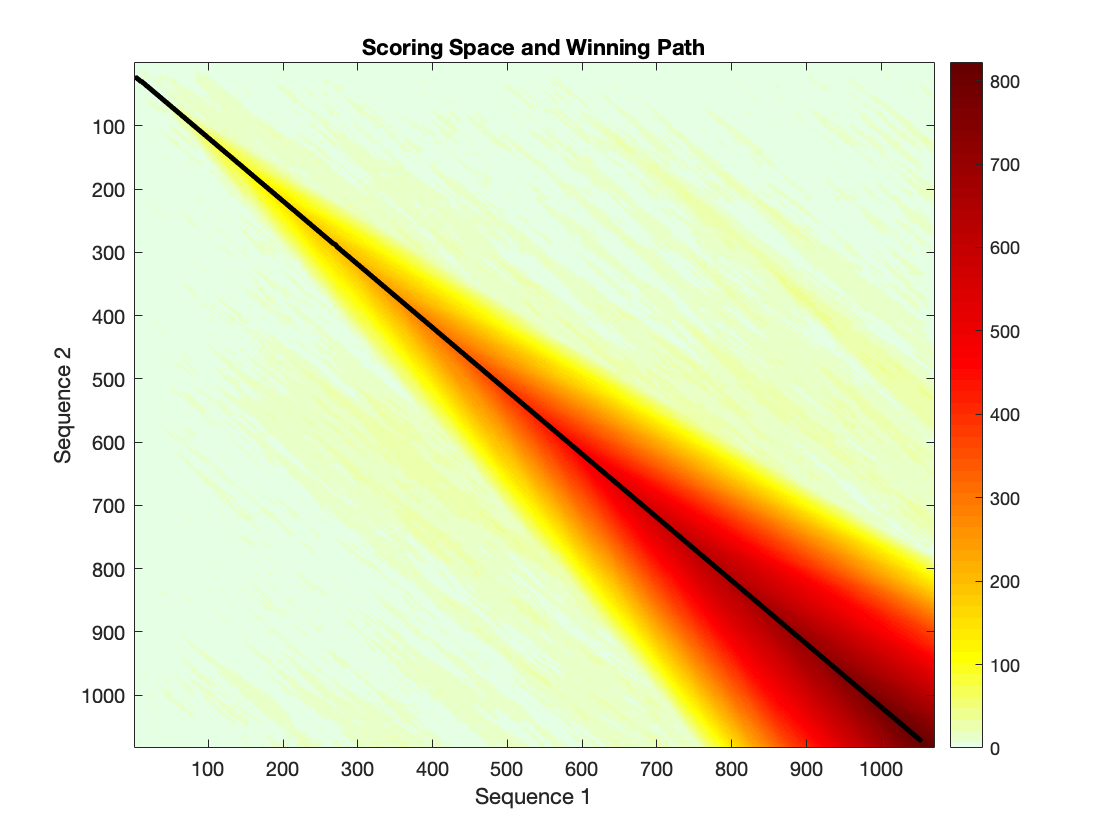

score = 821.1327

align = 3×1050 char array
    'CGGGGGAGGTGGAGATGGTGAAGGGGCAGCCGTTCGACGTGGGCCCGCGCTACACGCAGTTGCAGTACATCGGCGAGGGCGCGTACGGCATGGTCAGCTCGGCCTATGACCACGTGCGCAAGACTCGCGTGGCCATCAAGAAGATCAGCCCCTTCGAACATCAGACCTACTGCCAGCGCACGCTCCGGGAGATCCAGATCCTGCTGCGCTTCCGCCATGAGAATGTCATCGGCATCCGAGACATTCTGCGGGCGTCCACCCTGGAAGC-CATGAGAGATGTCTACATTGTGCAGGACCTGATGGAGACTGACCTGTACAAGTTGCTGAAAAGCCAGCAGCTGAGCAATGACCATATCTGCTACTTCCTCTACCAGATCCTGCGGGGCCTCAAGTACATCCACTCCGCCAACGTGCTCCACCGAGATCTAAAGCCCTCCAACCTGCTCATCAACACCACCTGCGACCTTAAGATTTGTGATTTCGGCCTGGCCCGGATTGCCGATCCTGAGCATGACCACACCGGCTTCCTGACGGAGTATGTGGCTACGCGCTGGTACCGGGCCCCAGAGATCATGCTGAACTCCAAGGGCTATACCAAGTCCATCGACATCTGGTCTGTGGGCTGCATTCTGGCTGAGATGCTCTCTAACCGGCCCATCTTCCCTGGCAAGCACTACCTGGATCAGCTCAACCACATTCTGGGCATCCTGGGCTCCCCATCCCAGGAGGACCTGAATTGTATCATCAACATGAAGGCCCGAAACTACCTACAGTCTCTGCCCTCCAAGACCAAGGTGGCTTGGGCCAAGCTTTTCCCCAAGTCAGACTCCAAAGCCCTTGACCTGCTGGACCGGATGTTAACCTTTAACCCCAATAAACGGATCACAGTGGAGGAAGCGCTGGCTCACCCCTACCTGGAGCAGTACTATGACCCGACGGATGAGCCAGTGGCCGAGGAGCCCTTCACC

start =      4
    24


figure;

[score, align, start] = swalign(ERK1.Sequence, ERK2.Sequence,'Alphabet','nt','Showscore', true)


%%%find the number of dashes/the length of sequence%%%

B = count(align(2, :),'|')

B = 797

A = length(ERK1.Sequence)

A = 1070

C = length(ERK2.Sequence)

C = 1083


Fraction_bpERK1_align_ERK2 = B/A

Fraction_bpERK1_align_ERK2 = 0.7449



% Part2. Perform an alignment of the aminoacid sequences of ERK1 and ERK2.
% What fraction of amino acids align?

ERK1_Protein = 'MAAAAAQGGGGGEPRRTEGVGPGVPGEVEMVKGQPFDVGPRYTQLQYIGEGAYGMVSSAYDHVRKTRVAIKKISPFEHQTYCQRTLREIQILLRFRHENVIGIRDILRASTLEAMRDVYIVQDLMETDLYKLLKSQQLSNDHICYFLYQILRGLKYIHSANVLHRDLKPSNLLINTTCDLKICDFGLARIADPEHDHTGFLTEYVATRWYRAPEIMLNSKGYTKSIDIWSVGCILAEMLSNRPIFPGKHYLDQLNHILGILGSPSQEDLNCIINMKARNYLQSLPSKTKVAWAKLFPKSDSKALDLLDRMLTFNPNKRITVEEALAHPYLEQYYDPTDEPVAEEPFTFAMELDDLPKERLKELIFQETARFQPGVLEAP'

ERK1_Protein = 'MAAAAAQGGGGGEPRRTEGVGPGVPGEVEMVKGQPFDVGPRYTQLQYIGEGAYGMVSSAYDHVRKTRVAIKKISPFEHQTYCQRTLREIQILLRFRHENVIGIRDILRASTLEAMRDVYIVQDLMETDLYKLLKSQQLSNDHICYFLYQILRGLKYIHSANVLHRDLKPSNLLINTTCDLKICDFGLARIADPEHDHTGFLTEYVATRWYRAPEIMLNSKGYTKSIDIWSVGCILAEMLSNRPIFPGKHYLDQLNHILGILGSPSQEDLNCIINMKARNYLQSLPSKTKVAWAKLFPKSDSKALDLLDRMLTFNPNKRITVEEALAHPYLEQYYDPTDEPVAEEPFTFAMELDDLPKERLKELIFQETARFQPGVLEAP'

ERK2_Protein = 'MAAAAAAGAGPEMVRGQVFDVGPRYTNLSYIGEGAYGMVCSAYDNVNKVRVAIKKISPFEHQTYCQRTLREIKILLRFRHENIIGINDIIRAPTIEQMKDVYIVQDLMETDLYKLLKTQHLSNDHICYFLYQILRGLKYIHSANVLHRDLKPSNLLLNTTCDLKICDFGLARVADPDHDHTGFLTEYVATRWYRAPEIMLNSKGYTKSIDIWSVGCILAEMLSNRPIFPGKHYLDQLNHILGILGSPSQEDLNCIINLKARNYLLSLPHKNKVPWNRLFPNADSKALDLLDKMLTFNPHKRIEVEQALAHPYLEQYYDPSDEPIAEAPFKFDMELDDLPKEKLKELIFEETARFQPGYRS'

ERK2_Protein = 'MAAAAAAGAGPEMVRGQVFDVGPRYTNLSYIGEGAYGMVCSAYDNVNKVRVAIKKISPFEHQTYCQRTLREIKILLRFRHENIIGINDIIRAPTIEQMKDVYIVQDLMETDLYKLLKTQHLSNDHICYFLYQILRGLKYIHSANVLHRDLKPSNLLLNTTCDLKICDFGLARVADPDHDHTGFLTEYVATRWYRAPEIMLNSKGYTKSIDIWSVGCILAEMLSNRPIFPGKHYLDQLNHILGILGSPSQEDLNCIINLKARNYLLSLPHKNKVPWNRLFPNADSKALDLLDKMLTFNPHKRIEVEQALAHPYLEQYYDPSDEPIAEAPFKFDMELDDLPKEKLKELIFEETARFQPGYRS'

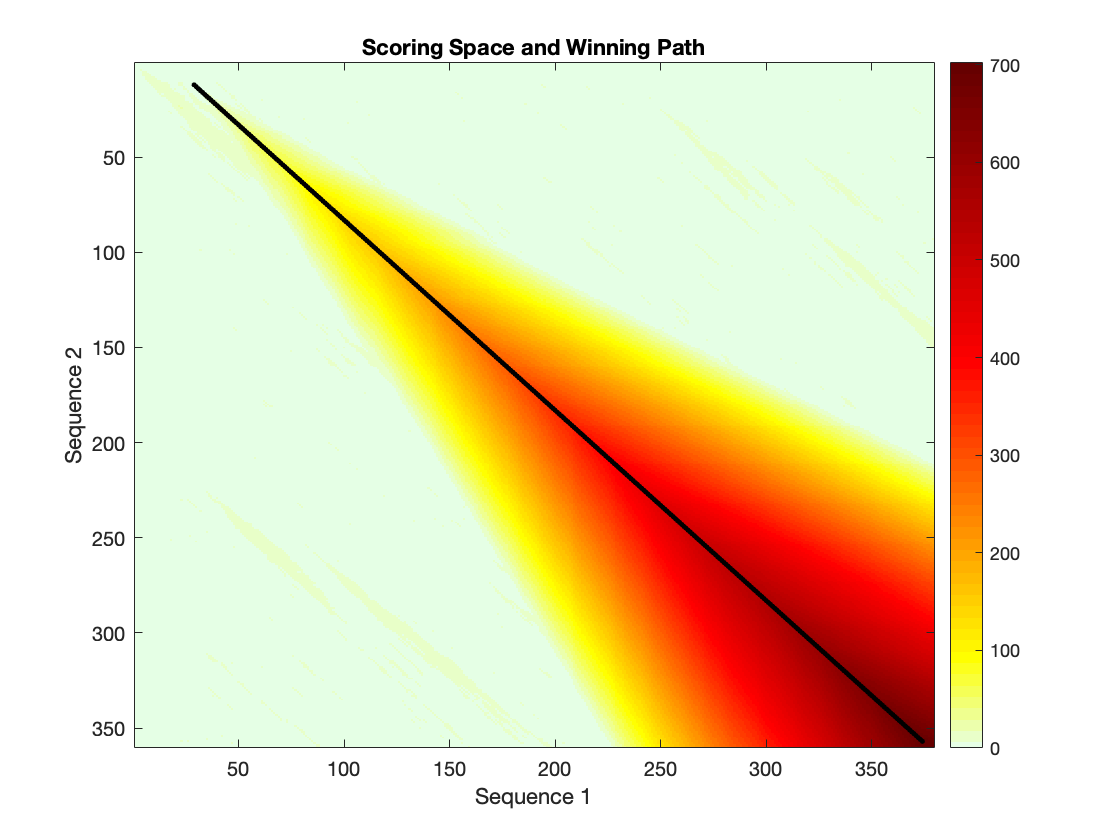

score = 701.6667

align_1 = 3×346 char array
    'EMVKGQPFDVGPRYTQLQYIGEGAYGMVSSAYDHVRKTRVAIKKISPFEHQTYCQRTLREIQILLRFRHENVIGIRDILRASTLEAMRDVYIVQDLMETDLYKLLKSQQLSNDHICYFLYQILRGLKYIHSANVLHRDLKPSNLLINTTCDLKICDFGLARIADPEHDHTGFLTEYVATRWYRAPEIMLNSKGYTKSIDIWSVGCILAEMLSNRPIFPGKHYLDQLNHILGILGSPSQEDLNCIINMKARNYLQSLPSKTKVAWAKLFPKSDSKALDLLDRMLTFNPNKRITVEEALAHPYLEQYYDPTDEPVAEEPFTFAMELDDLPKERLKELIFQETARFQPG'
    '|||:|| ||||||||:|:|||||||||| ||||:| |:|||||||||||||||||||||||:|||||||||:||| ||:|| |:| |:||||||||||||||||||:|:||||||||||||||||||||||||||||||||||||:|||||||||||||||:|||:||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||:|||||| ||| |:|| | :|||::|||||||||:||||||:||| ||:|||||||||||||:|||:|| || | |||||||||:||||||:||||||||'
    'EMVRGQVFDVGPRYTNLSYIGEGAYGMVCSAYDNVNKVRVAIKKISPFEHQTYCQRTLREIKILLRFRHENIIGINDIIRAPTIEQMKDVYIVQDLMETDLYKLLKTQHLSNDHICYFLYQILRGLKYIHSANVLHRDLKPSNLLLNTTCDLKICDFGLARVADPDHDHTGFLTEYVATRWYRAPEIMLNSKGYTKSIDIWSVGCILAEMLSNRPIFPGKHYLDQLNHILGILGSPSQEDLNCIINLKARNYLLSLPHKNKV

start =     29
    12



[score, align_1, start] = swalign(ERK1_Protein, ERK2_Protein,'Alphabet','AA','Showscore',true)


D = count(align_1(2, :),'|')

D = 305

E = length(ERK1_Protein)

E = 379

F = length(ERK2_Protein)

F = 360

Fraction_AAERK1_align_ERK2 = D/E   %Fraction of ERK1 amino acid that aligns with ERK2

Fraction_AAERK1_align_ERK2 = 0.8047

Fraction_AAERK2_align_ERK1 = D/F   %Fraction of ERK2 amino acid that aligns with ERK1

Fraction_AAERK2_align_ERK1 = 0.8472



% Part 3.  Use the NCBI tools to get mRNA sequences for the mouse genes ERK1 and
% ERK2 and align both the coding DNA sequences and protein sequences to the
% human versions. How similar are they?

% for MAPK3 Mouse :  NM_011952.2
%for MAPK1: NM_001038663.1
ERK1_MRNA_Mouse = fastaread('sequence-3.txt') %Obtained from NCBI Nucleotide and only chose to download coding sequences. 

ERK1_MRNA_Mouse = struct with fields:
      Header: 'lcl|NM_011952.2_cds_NP_036082.1_1 [gene=Mapk3] [db_xref=CCDS:CCDS21841.1] '
    Sequence: 'ATGGCGGCGGCGGCGGCGGCTCCGGGGGGCGGGGGCGGGGAGCCCAGGGGAACTGCTGGGGTCGTCCCGGTGGTCCCCGGGGAGGTGGAGGTGGTGAAGGGGCAGCCATTCGATGTGGGCCCACGCTACACGCAGCTGCAGTACATCGGCGAGGGCGCGTACGGCATGGTCAGCTCAGCTTATGACCACGTGCGCAAGACCAGAGTGGCCATCAAGAAGATCAGCCCCTTTGAGCATCAAACCTACTGTCAGCGCACGCTGAGGGAGATCCAGATCTTGCTGCGATTCCGCCATGAGAATGTTATAGGCATCCGAGACATCCTCAGAGCGCCCACCCTGGAAGCCATGAGAGATGTTTACATTGTTCAGGACCTCATGGAGACAGACCTGTACAAGCTGCTTAAAAGCCAGCAGCTGAGCAATGACCACATCTGCTACTTCCTCTACCAGATCCTCCGGGGCCTCAAGTATATACACTCAGCCAATGTGCTGCACCGGGACCTGAAGCCTTCCAATCTGCTTATCAACACCACCTGCGACCTTAAGATCTGTGATTTTGGCCTGGCCCGGATTGCTGACCCTGAGCACGACCACACTGGCTTTCTGACGGAGTATGTGGCCACACGCTGGTACCGAGCCCCAGAGATCATGCTTAATTCCAAGGGCTACACCAAATCCATCGACATCTGGTCTGTGGGCTGCATTCTGGCTGAGATGCTCTCCAACCGGCCCATCTTCCCCGGCAAGCACTACCTGGACCAGCTCAACCACATTCTAGGTATCTTGGGTTCCCCATCCCAGGAGGACCTTAATTGCATCATTAACATGAAGGCCCGAAACTACCTGCAGTCTCTGC

ERK2_MRNA_Mouse = fastaread('sequence-4.txt')

ERK2_MRNA_Mouse = struct with fields:
      Header: 'lcl|NM_001038663.1_cds_NP_001033752.1_1 [gene=Mapk1] [db_xref=CCDS:CCDS27992.1] '
    Sequence: 'ATGGCGGCGGCGGCGGCGGCGGGCCCGGAGATGGTCCGCGGGCAGGTGTTCGACGTAGGGCCGCGCTACACCAACCTCTCGTACATCGGAGAAGGCGCCTACGGCATGGTTTGCTCTGCTTATGATAATCTCAACAAAGTTCGAGTTGCTATCAAGAAAATCAGTCCTTTTGAGCACCAGACCTACTGTCAAAGAACCCTAAGAGAGATAAAAATCTTACTGCGCTTCAGACATGAGAACATCATTGGCATCAATGACATCATCCGGGCACCAACCATTGAGCAAATGAAAGATGTATATATAGTACAGGACCTCATGGAGACGGACCTTTACAAGCTCTTGAAGACACAGCACCTCAGCAATGACCACATCTGCTATTTTCTTTATCAGATCCTGAGAGGGCTAAAGTATATCCATTCAGCTAACGTTCTGCACCGTGACCTCAAGCCTTCCAACCTCCTGCTGAACACCACTTGTGATCTCAAGATCTGTGACTTTGGCCTTGCCCGTGTTGCAGATCCAGATCATGATCACACAGGGTTCTTGACAGAGTACGTAGCCACACGTTGGTACAGAGCTCCAGAAATTATGTTGAATTCCAAGGGTTATACCAAGTCCATTGATATTTGGTCTGTGGGCTGCATCCTGGCAGAGATGCTATCCAACAGGCCTATCTTCCCAGGAAAGCATTACCTTGACCAGCTGAATCACATCCTGGGTATTCTTGGATCTCCATCACAGGAAGATCTGAATTGTATAATAAATTTAAAAGCTAGAAACTATTTGCTTTCTCTCCCGCACAAAAATAAGGTGCCATGGAACAGGTTGTTCCCAAATGCTGACTCCAAAG

ERK1_AA_Mouse = 'MAAAAAAPGGGGGEPRGTAGVVPVVPGEVEVVKGQPFDVGPRYTQLQYIGEGAYGMVSSAYDHVRKTRVAIKKISPFEHQTYCQRTLREIQILLRFRHENVIGIRDILRAPTLEAMRDVYIVQDLMETDLYKLLKSQQLSNDHICYFLYQILRGLKYIHSANVLHRDLKPSNLLINTTCDLKICDFGLARIADPEHDHTGFLTEYVATRWYRAPEIMLNSKGYTKSIDIWSVGCILAEMLSNRPIFPGKHYLDQLNHILGILGSPSQEDLNCIINMKARNYLQSLPSKTKVAWAKLFPKSDSKALDLLDRMLTFNPNKRITVEEALAHPYLEQYYDPTDEPVAEEPFTFDMELDDLPKERLKELIFQETARFQPGAPEGP'

ERK1_AA_Mouse = 'MAAAAAAPGGGGGEPRGTAGVVPVVPGEVEVVKGQPFDVGPRYTQLQYIGEGAYGMVSSAYDHVRKTRVAIKKISPFEHQTYCQRTLREIQILLRFRHENVIGIRDILRAPTLEAMRDVYIVQDLMETDLYKLLKSQQLSNDHICYFLYQILRGLKYIHSANVLHRDLKPSNLLINTTCDLKICDFGLARIADPEHDHTGFLTEYVATRWYRAPEIMLNSKGYTKSIDIWSVGCILAEMLSNRPIFPGKHYLDQLNHILGILGSPSQEDLNCIINMKARNYLQSLPSKTKVAWAKLFPKSDSKALDLLDRMLTFNPNKRITVEEALAHPYLEQYYDPTDEPVAEEPFTFDMELDDLPKERLKELIFQETARFQPGAPEGP'

ERK2_AA_MOUSE = 'MAAAAAAGPEMVRGQVFDVGPRYTNLSYIGEGAYGMVCSAYDNLNKVRVAIKKISPFEHQTYCQRTLREIKILLRFRHENIIGINDIIRAPTIEQMKDVYIVQDLMETDLYKLLKTQHLSNDHICYFLYQILRGLKYIHSANVLHRDLKPSNLLLNTTCDLKICDFGLARVADPDHDHTGFLTEYVATRWYRAPEIMLNSKGYTKSIDIWSVGCILAEMLSNRPIFPGKHYLDQLNHILGILGSPSQEDLNCIINLKARNYLLSLPHKNKVPWNRLFPNADSKALDLLDKMLTFNPHKRIEVEQALAHPYLEQYYDPSDEPIAEAPFKFDMELDDLPKEKLKELIFEETARFQPGYRS'

ERK2_AA_MOUSE = 'MAAAAAAGPEMVRGQVFDVGPRYTNLSYIGEGAYGMVCSAYDNLNKVRVAIKKISPFEHQTYCQRTLREIKILLRFRHENIIGINDIIRAPTIEQMKDVYIVQDLMETDLYKLLKTQHLSNDHICYFLYQILRGLKYIHSANVLHRDLKPSNLLLNTTCDLKICDFGLARVADPDHDHTGFLTEYVATRWYRAPEIMLNSKGYTKSIDIWSVGCILAEMLSNRPIFPGKHYLDQLNHILGILGSPSQEDLNCIINLKARNYLLSLPHKNKVPWNRLFPNADSKALDLLDKMLTFNPHKRIEVEQALAHPYLEQYYDPSDEPIAEAPFKFDMELDDLPKEKLKELIFEETARFQPGYRS'

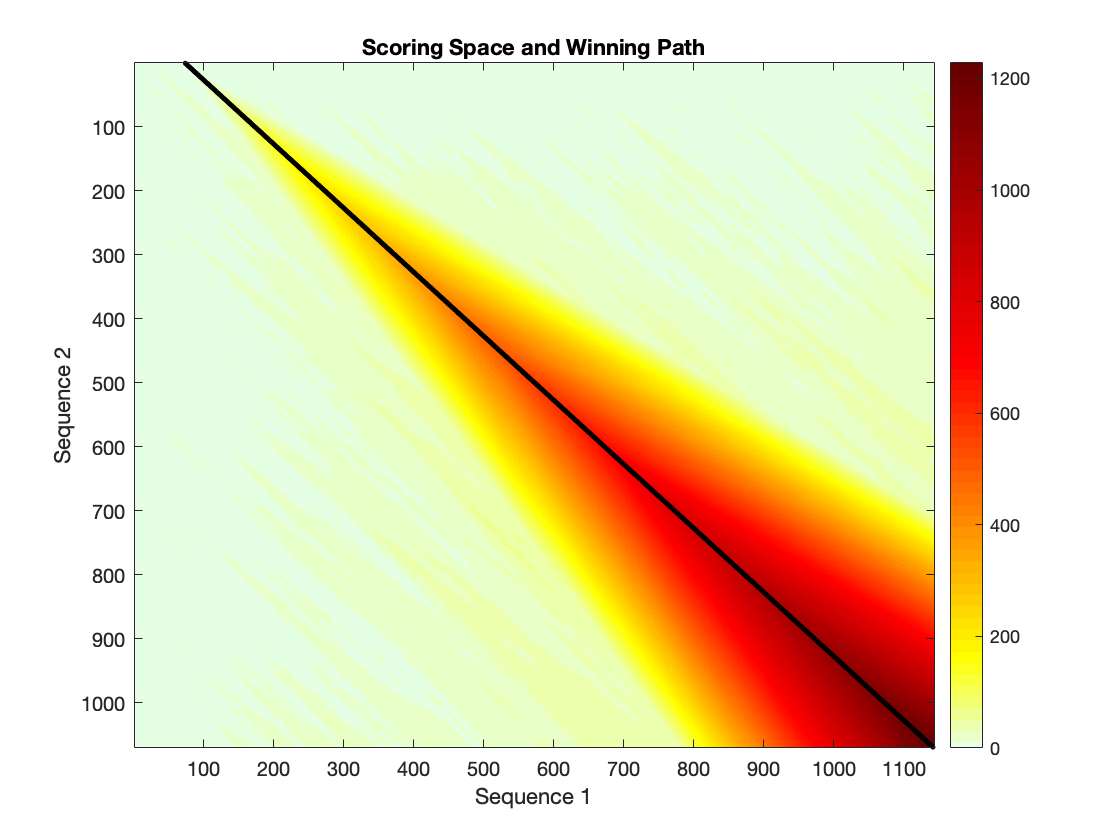

score = 1.2277e+03

align_2 = 3×1069 char array
    'TCCCCGGGGAGGTGGAGGTGGTGAAGGGGCAGCCATTCGATGTGGGCCCACGCTACACGCAGCTGCAGTACATCGGCGAGGGCGCGTACGGCATGGTCAGCTCAGCTTATGACCACGTGCGCAAGACCAGAGTGGCCATCAAGAAGATCAGCCCCTTTGAGCATCAAACCTACTGTCAGCGCACGCTGAGGGAGATCCAGATCTTGCTGCGATTCCGCCATGAGAATGTTATAGGCATCCGAGACATCCTCAGAGCGCCCACCCTGGAAGCCATGAGAGATGTTTACATTGTTCAGGACCTCATGGAGACAGACCTGTACAAGCTGCTTAAAAGCCAGCAGCTGAGCAATGACCACATCTGCTACTTCCTCTACCAGATCCTCCGGGGCCTCAAGTATATACACTCAGCCAATGTGCTGCACCGGGACCTGAAGCCTTCCAATCTGCTTATCAACACCACCTGCGACCTTAAGATCTGTGATTTTGGCCTGGCCCGGATTGCTGACCCTGAGCACGACCACACTGGCTTTCTGACGGAGTATGTGGCCACACGCTGGTACCGAGCCCCAGAGATCATGCTTAATTCCAAGGGCTACACCAAATCCATCGACATCTGGTCTGTGGGCTGCATTCTGGCTGAGATGCTCTCCAACCGGCCCATCTTCCCCGGCAAGCACTACCTGGACCAGCTCAACCACATTCTAGGTATCTTGGGTTCCCCATCCCAGGAGGACCTTAATTGCATCATTAACATGAAGGCCCGAAACTACCTGCAGTCTCTGCCCTCGAAAACCAAGGTGGCTTGGGCCAAGCTCTTTCCTAAATCTGACTCCAAAGCTCTTGACCTGCTGGACCGGATGTTAACCTTCAACCCAAACAAGCGCATCACAGTAGAGGAAGCGCTGGCTCACCCTTACCTGGAACAGTACTACGATCCGACAGATGAGCCAGTGGCCGAGGAGCCATT

start =     74
     1



%%% Alignments %%%

[score, align_2, start] = swalign(ERK1_MRNA_Mouse.Sequence, ERK1.Sequence,'Alphabet','nt','Showscore', true)

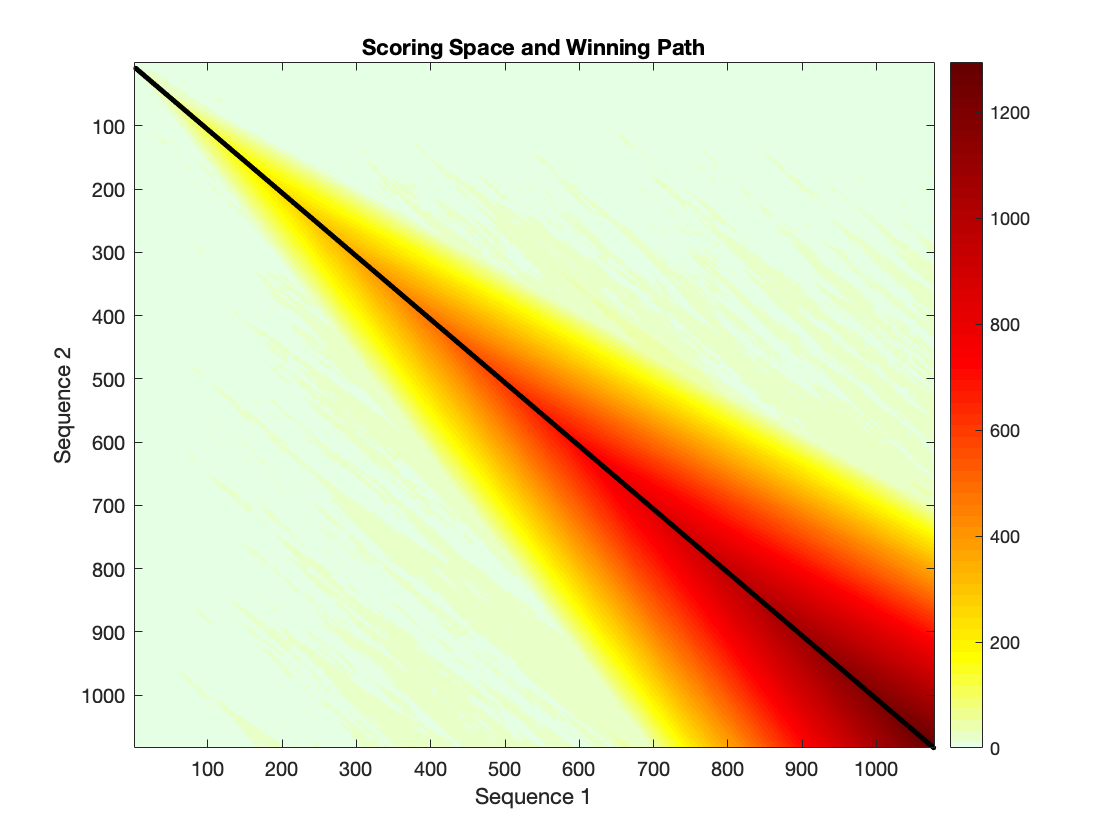

Score = 1.2934e+03

align_3 = 3×1075 char array
    'GGCGGCGGCGGCGGCGGCGGGCCCGGAGATGGTCCGCGGGCAGGTGTTCGACGTAGGGCCGCGCTACACCAACCTCTCGTACATCGGAGAAGGCGCCTACGGCATGGTTTGCTCTGCTTATGATAATCTCAACAAAGTTCGAGTTGCTATCAAGAAAATCAGTCCTTTTGAGCACCAGACCTACTGTCAAAGAACCCTAAGAGAGATAAAAATCTTACTGCGCTTCAGACATGAGAACATCATTGGCATCAATGACATCATCCGGGCACCAACCATTGAGCAAATGAAAGATGTATATATAGTACAGGACCTCATGGAGACGGACCTTTACAAGCTCTTGAAGACACAGCACCTCAGCAATGACCACATCTGCTATTTTCTTTATCAGATCCTGAGAGGGCTAAAGTATATCCATTCAGCTAACGTTCTGCACCGTGACCTCAAGCCTTCCAACCTCCTGCTGAACACCACTTGTGATCTCAAGATCTGTGACTTTGGCCTTGCCCGTGTTGCAGATCCAGATCATGATCACACAGGGTTCTTGACAGAGTACGTAGCCACACGTTGGTACAGAGCTCCAGAAATTATGTTGAATTCCAAGGGTTATACCAAGTCCATTGATATTTGGTCTGTGGGCTGCATCCTGGCAGAGATGCTATCCAACAGGCCTATCTTCCCAGGAAAGCATTACCTTGACCAGCTGAATCACATCCTGGGTATTCTTGGATCTCCATCACAGGAAGATCTGAATTGTATAATAAATTTAAAAGCTAGAAACTATTTGCTTTCTCTCCCGCACAAAAATAAGGTGCCATGGAACAGGTTGTTCCCAAATGCTGACTCCAAAGCTCTGGATTTACTGGATAAAATGTTGACATTTAACCCTCACAAGAGGATTGAAGTTGAACAGGCTCTGGCCCACCCATACCTGGAGCAGTATTATGACCCAAGTGATGAGCCCATTGCT

start =      3
     9



[Score, align_3, start] = swalign(ERK2_MRNA_Mouse.Sequence, ERK2.Sequence,'Alphabet','nt','Showscore',true)

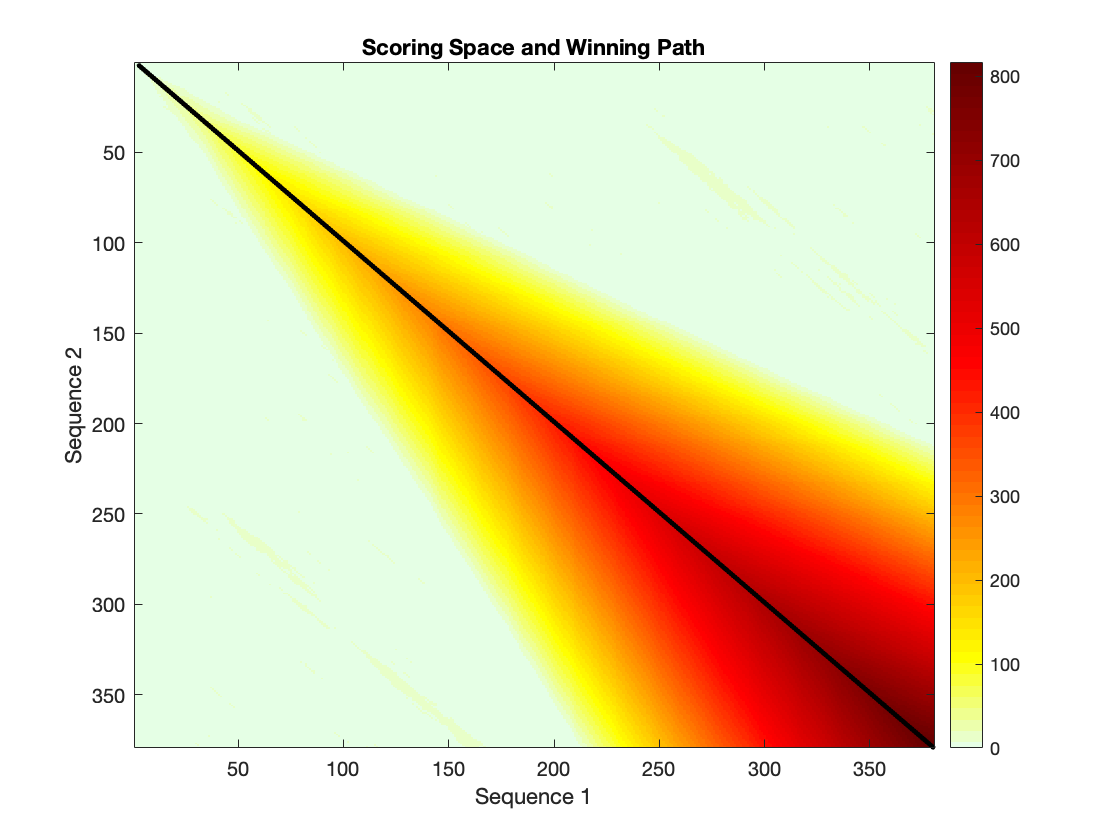

Score = 816

align_4 = 3×378 char array
    'AAAAAPGGGGGEPRGTAGVVPVVPGEVEVVKGQPFDVGPRYTQLQYIGEGAYGMVSSAYDHVRKTRVAIKKISPFEHQTYCQRTLREIQILLRFRHENVIGIRDILRAPTLEAMRDVYIVQDLMETDLYKLLKSQQLSNDHICYFLYQILRGLKYIHSANVLHRDLKPSNLLINTTCDLKICDFGLARIADPEHDHTGFLTEYVATRWYRAPEIMLNSKGYTKSIDIWSVGCILAEMLSNRPIFPGKHYLDQLNHILGILGSPSQEDLNCIINMKARNYLQSLPSKTKVAWAKLFPKSDSKALDLLDRMLTFNPNKRITVEEALAHPYLEQYYDPTDEPVAEEPFTFDMELDDLPKERLKELIFQETARFQPGAPEGP'
    '||||| |||||||| | || | ||||||:||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||| |||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||| |||||||||||||||||||||||||: |:|'
    'AAAAAQGGGGGEPRRTEGVGPGVPGEVEMVKGQPFDVGPRYTQLQYIGEGAYGMVSSAYDHVRKTRVAIKKISPFEHQTYCQRTLREIQILLRFRHENVIGIRDILRASTLEAMRDVYIVQDLMETDLYKLLKSQQLSNDHICYFLYQILRGLKYIHSANVLHRDLKPSNLLINTTCDLKICDFGLARIADPEHDHTG

start =      3
     2



[Score, align_4, start] = swalign (ERK1_AA_Mouse, ERK1_Protein,'Alphabet','AA','Showscore', true)

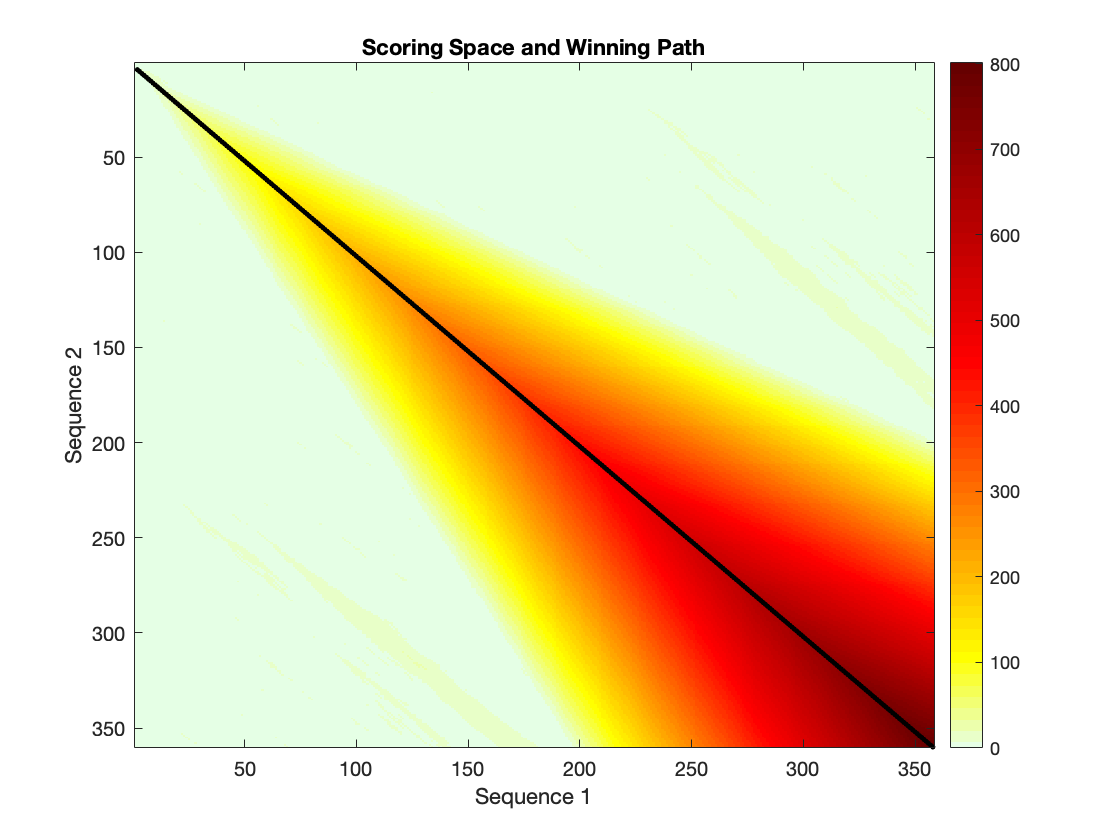

Score = 801

align_5 = 3×357 char array
    'AAAAAAGPEMVRGQVFDVGPRYTNLSYIGEGAYGMVCSAYDNLNKVRVAIKKISPFEHQTYCQRTLREIKILLRFRHENIIGINDIIRAPTIEQMKDVYIVQDLMETDLYKLLKTQHLSNDHICYFLYQILRGLKYIHSANVLHRDLKPSNLLLNTTCDLKICDFGLARVADPDHDHTGFLTEYVATRWYRAPEIMLNSKGYTKSIDIWSVGCILAEMLSNRPIFPGKHYLDQLNHILGILGSPSQEDLNCIINLKARNYLLSLPHKNKVPWNRLFPNADSKALDLLDKMLTFNPHKRIEVEQALAHPYLEQYYDPSDEPIAEAPFKFDMELDDLPKEKLKELIFEETARFQPGYRS'
    '||||:|||||||||||||||||||||||||||||||||||||:||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||'
    'AAAAGAGPEMVRGQVFDVGPRYTNLSYIGEGAYGMVCSAYDNVNKVRVAIKKISPFEHQTYCQRTLREIKILLRFRHENIIGINDIIRAPTIEQMKDVYIVQDLMETDLYKLLKTQHLSNDHICYFLYQILRGLKYIHSANVLHRDLKPSNLLLNTTCDLKICDFGLARVADPDHDHTGFLTEYVATRWYRAPEIMLNSKGYTKSIDIWSVGCILAEMLSNRPIFPGKHYLDQLNHILGI

start =      2
     4



[Score, align_5, start] = swalign(ERK2_AA_MOUSE, ERK2_Protein, 'Alphabet','AA','Showscore',true)


%%% Assessing how similar they are comparing to Human %%%
H = count(align_2(2, :), '|')

H = 967

I = count(align_3(2, :), '|')

I = 996

J = count(align_4(2, :), '|')

J = 367

K = count(align_5(2, :), '|')

K = 355


ERK1_DNA_FRACTION = H/A  

ERK1_DNA_FRACTION = 0.9037

ERK2_DNA_FRACTION = I/C

ERK2_DNA_FRACTION = 0.9197

ERK1_AA_FRACTION = J/E

ERK1_AA_FRACTION = 0.9683

ERK2_AA_FRACTION = K/F

ERK2_AA_FRACTION = 0.9861


%%% Conclusion %%%%

%Looking at the values of fractions above, we can conclude the mouse ERK1
%and ERK2 in terms of DNA sequences and amino acid sequences, compared to
%ERK1 and ERK2 in humans, they are very similar). The Fractions are very
%high. Also, Please note that the fraction was calculated in relation to
%human ERK1 and ERK2, not the mouse: alignment/lengthofhumanDNA/AA.

%%% Assessing how similar they are comparing to Mouse%%%

M = length(ERK1_MRNA_Mouse.Sequence)

M = 1143

N = length(ERK2_MRNA_Mouse.Sequence)

N = 1077

O = length(ERK1_AA_Mouse)

O = 380

P = length(ERK2_AA_MOUSE)

P = 358


ERK1_FRACTION_DNA = H/M

ERK1_FRACTION_DNA = 0.8460

ERK2_FRACTION_DNA = I/N

ERK2_FRACTION_DNA = 0.9248

ERK1_FRACTION_AA = J/O

ERK1_FRACTION_AA = 0.9658

ERK2_FRACTION_AA = K/P

ERK2_FRACTION_AA = 0.9916


%Same Conlcusion as Above%

